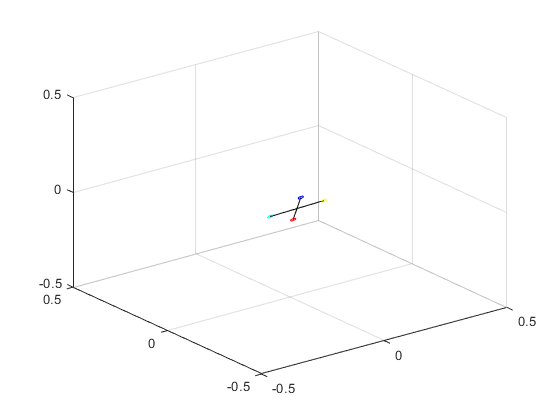


l1=zeros(101,3);
l2=zeros(101,3);
R1=zeros(101,3);
R2=zeros(101,3);
R3=zeros(101,3);
R4=zeros(101,3);
r=zeros(101,3);
for i=1:101
    l1(i,1)=-0.1+(i-1)*0.002;
    l2(i,2)=-0.1+(i-1)*0.002;
    alpha=pi*2*((i-1)/100);
    r(i,:)=(eul2rotm([alpha 0 0])*[0.01;0;0]).';
end
R1=r+[0 0.1 0];
R2=r+[0.1 0 0];
R3=r+[0 -0.1 0];
R4=r+[-0.1 0 0];
global parms;
parms.l1=l1;
parms.l2=l2;
parms.R1=R1;
parms.R2=R2;
parms.R3=R3;
parms.R4=R4;
anim(out.tout,out.simout,1/24); % animate the system and save the simulation video

function anim(t,x,ts)
[te,xe]=even_sample(t,x,2400);

figure;

%save as a video
spwriter = VideoWriter('video_Quaternion02.avi');
set(spwriter, 'FrameRate', 1/ts,'Quality',100);
open(spwriter);


figure_x_limits = [-0.5 0.5];
figure_y_limits = [-0.5 0.5];
figure_z_limits = [-0.5 0.5];

axes1 = axes;
%set(axes,'XLim',figure_x_limits,'YLim',figure_y_limits,'ZLim',figure_z_limits);
% set(axes,'Position',[0 0 1 1]);
%set(axes,'Color','w');
% Points=zeros(length(te),2);
for k = 1:length(te)
    drawone(axes1, xe(k,:));
    set(axes1,'XLim',figure_x_limits,'YLim',figure_y_limits,'ZLim',figure_z_limits);
    grid on;
    drawnow;
    pause(ts);
    frame = getframe(gcf);
    writeVideo(spwriter, frame);
end

end


function [Et, Ex] = even_sample(t, x, Fs)
%       CONVERTS A RANDOMLY SAMPLED SIGNAL SET INTO AN EVENLY SAMPLED
%       SIGNAL SET (by interpolation)
% Obtain the process related parameters
N = size(x, 2);    % number of signals to be interpolated
M = size(t, 1);    % Number of samples provided
t0 = t(1,1);       % Initial time
tf = t(M,1);       % Final time
EM = (tf-t0)*Fs;   % Number of samples in the evenly sampled case with
                   % the specified sampling frequency
Et = linspace(t0, tf, EM)';

% Using linear interpolation (used to be cubic spline interpolation)
% and re-sample each signal to obtain the evenly sampled forms
for s = 1:N
  Ex(:,s) = interp1(t(:,1), x(:,s), Et(:,1)); 
end
end

function drawone(parent, x)
global parms;
% draw the robot at the current frame
tem = get(parent,'Children');
delete(tem);

R=eul2rotm([x(3) x(2) x(1)]);

l1=zeros(101,3);
l2=zeros(101,3);
R1=zeros(101,3);
R2=zeros(101,3);
R3=zeros(101,3);
R4=zeros(101,3);

for i=1:101
l1(i,:)=(R*parms.l1(i,:).').'+x(4:6);
l2(i,:)=(R*parms.l2(i,:).').'+x(4:6);
R1(i,:)=(R*parms.R1(i,:).').'+x(4:6);
R2(i,:)=(R*parms.R2(i,:).').'+x(4:6);
R3(i,:)=(R*parms.R3(i,:).').'+x(4:6);
R4(i,:)=(R*parms.R4(i,:).').'+x(4:6);
end

plot3(l1(:,1),l1(:,2),l1(:,3),'black',l2(:,1),l2(:,2),l2(:,3),'black',R1(:,1),R1(:,2),R1(:,3),'red',R2(:,1),R2(:,2),R2(:,3),'yellow',R3(:,1),R3(:,2),R3(:,3),'blue',R4(:,1),R4(:,2),R4(:,3),'cyan');
end